s = tf("s");
k = 16;
T = 1;

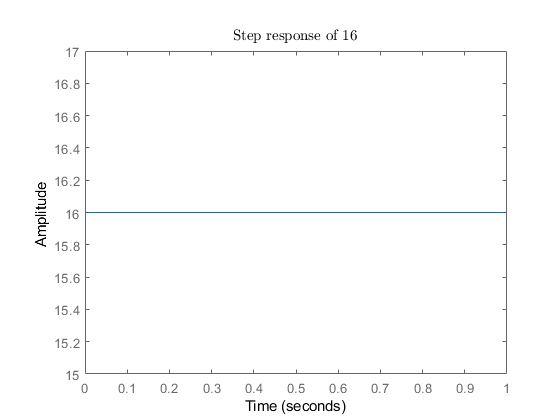

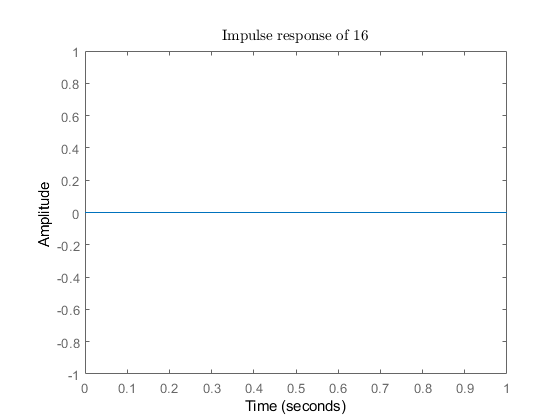

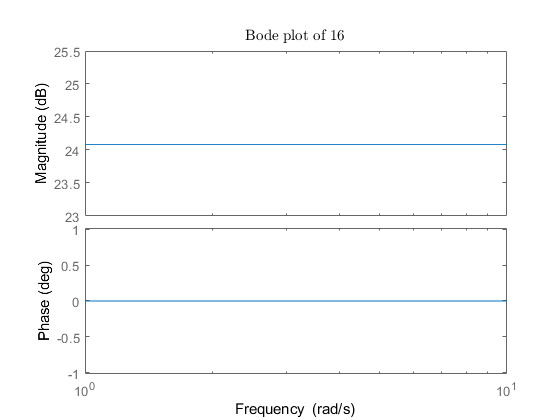

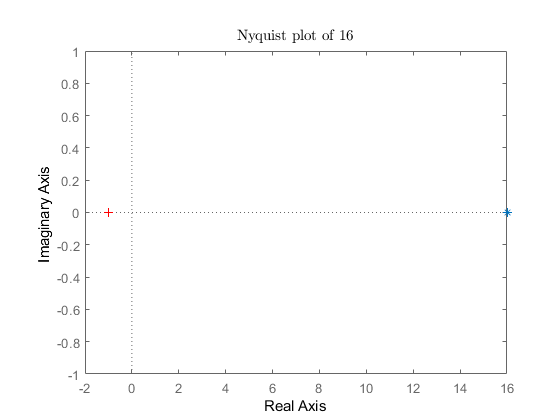

%1 - simple amplifying
H = tf(k);
plot_all_and_save(H)

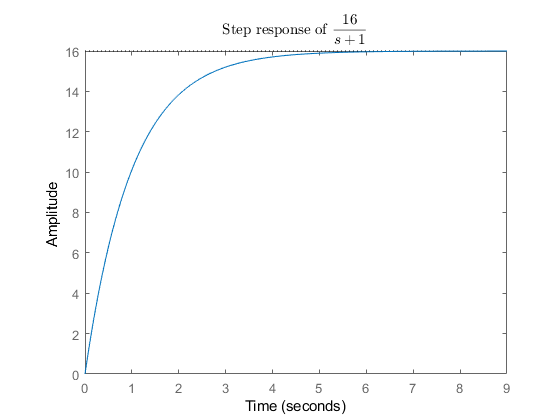

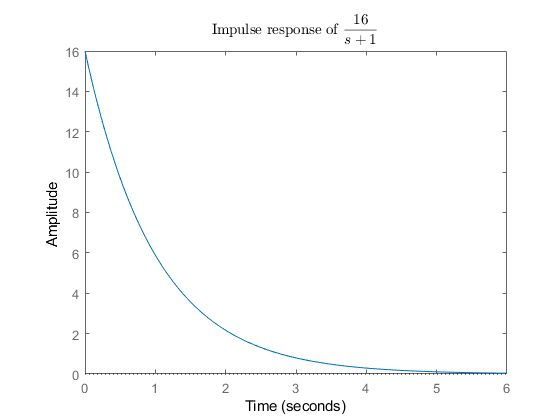

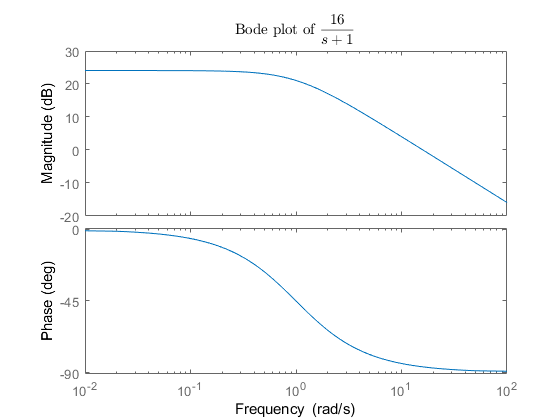

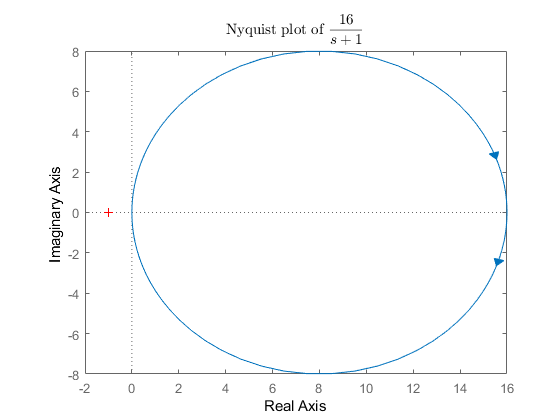

%2 - 1st order aperiodic
H = k/(1+T*s);
plot_all_and_save(H)

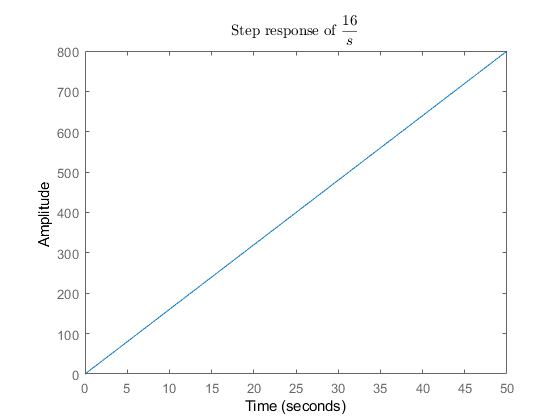

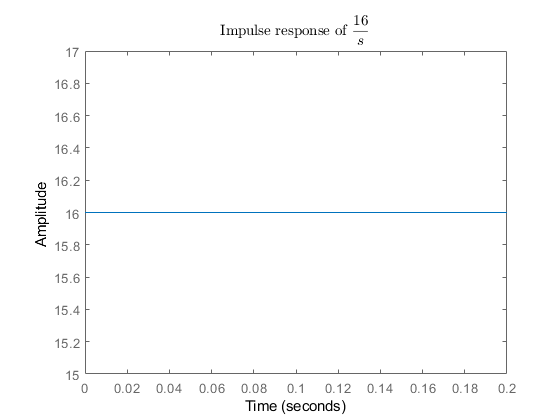

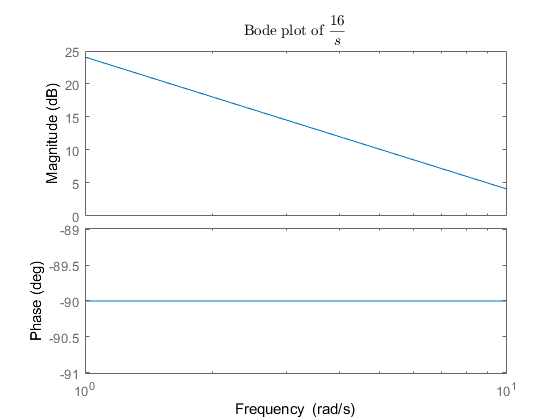

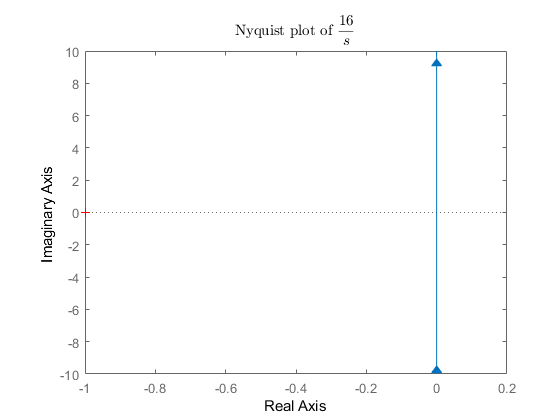

%3 - simple integrating
H = k/s;
plot_all_and_save(H)

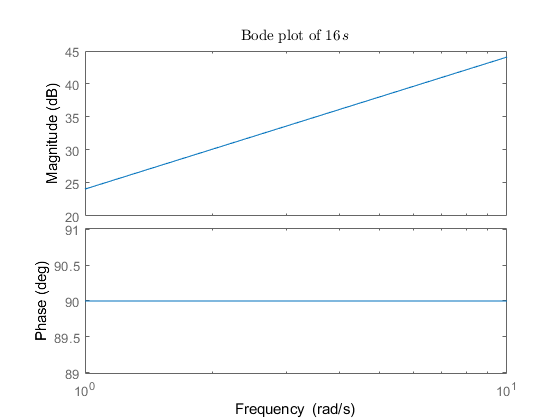

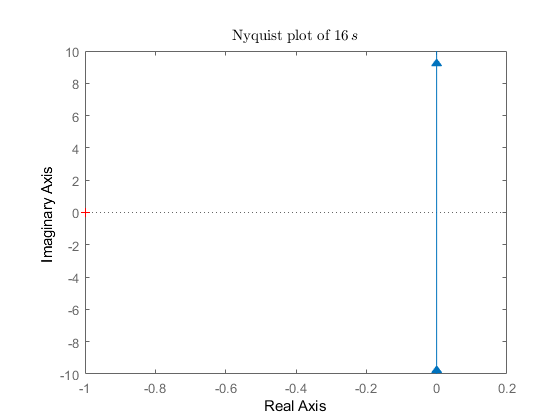

%4 - simple differentiating
H = k*s;
plot_all_and_save(H)

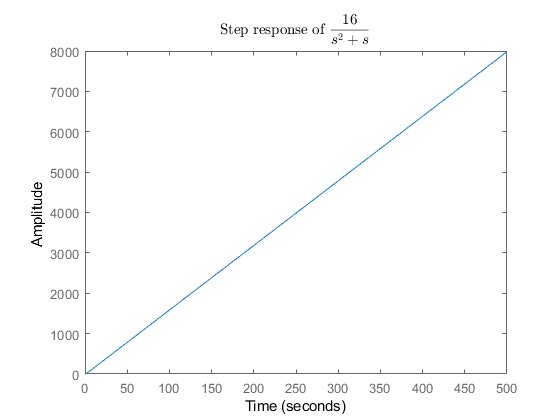

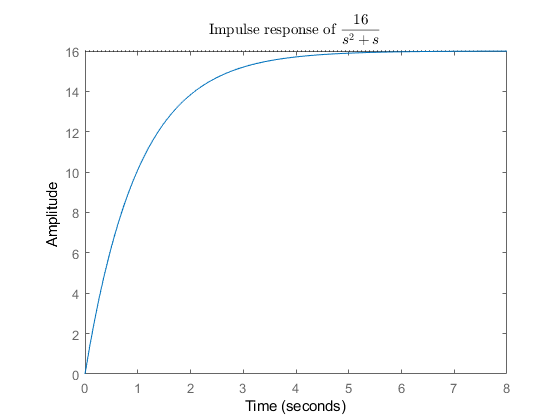

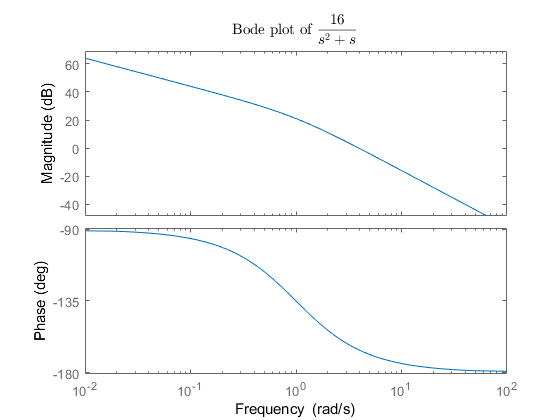

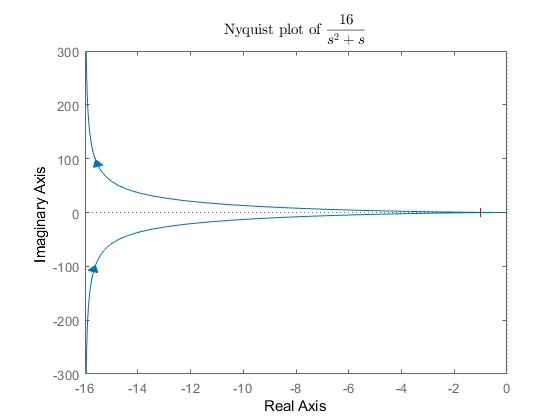

%5 - real integrating
H = tf([k], [T 1 0]);
plot_all_and_save(H)

%6 - real differentiating
H = tf([k], [T, 1]);
plot_all_and_save(H)

function plot_all_and_save(H)
    syms s;
    [num, den] = tfdata(H);
    sym_H = poly2sym(sym(num), s) / poly2sym(sym(den), s);
    sym_title = latex(sym_H);
    %
    
    mkdir plots;
    
    try %doesn't plot for some specific TFs (simple differentiating)
        figure;
        step(H);
        title(sprintf("Step response of $$ %s $$", sym_title), "Interpreter", "Latex");
        saveas(gcf, sprintf("plots/Step of %s.jpg", strrep(sym_title, '\', '')));
    
        figure;
        impulse(H);
        title(sprintf("Impulse response of $$ %s $$", sym_title), "Interpreter", "Latex");
        saveas(gcf, sprintf("plots/Impulse of %s.jpg", strrep(sym_title, '\', '')));
    end
   
    figure;
    bode(H);
    title(sprintf("Bode plot of $$ %s $$", sym_title), "Interpreter", "Latex");
    saveas(gcf, sprintf("plots/Bode of %s.jpg", strrep(sym_title, '\', '')));
    
    figure;
    nyquist(H);
    title(sprintf("Nyquist plot of $$ %s $$", sym_title), "Interpreter", "Latex");
    saveas(gcf, sprintf("plots/Nyquist of %s.jpg", strrep(sym_title, '\', '')));
end